## AOMIC PIOP2 Replication Sample - Whole-Brain Coupling Plot Across Conditions 

Computation of coupling measure-specific brain-average coupling values for all four conditions, taking the mean across the four measure-specific brain-average coupling values per condition and creating the violin plot visualizing condition-specific differences in brain-average SC-FC coupling. 

Before running this script: 

- run all scripts in AOMIC Data Prep 

**1. Compute brain-average coupling values **

1.1. Resting-state 

for i = 1:180
    whole_brain_values_AOMIC_PIOP2_rest{i,1} = mean(final_r_all_AOMIC_PIOP2_rest_180{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP2_rest{i,2} = mean(final_r_all_AOMIC_PIOP2_rest_180{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP2_rest{i,3} = mean(final_r_all_AOMIC_PIOP2_rest_180{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP2_rest{i,4} = mean(final_r_all_AOMIC_PIOP2_rest_180{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP2_rest_table = cell2table(whole_brain_values_AOMIC_PIOP2_rest);
 whole_brain_values_AOMIC_PIOP2_rest_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP2_rest_table = 180×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.24049    0.24388    0.26184    0.19397
    0.18809    0.22514    0.23472    0.21443
    0.21149    0.24024      0.251    0.20192
    0.21095    0.21691    0.22397    0.17247
     0.2385    0.25695    0.27696    0.21922
    0.21308    0.22182    0.23073    0.17766
    0.25433    0.24283    0.26575    0.26113
    0.27584    0.27236    0.29538    0.25944
    0.20416    0.22716    0.23169    0.15163
    0.19635    0.21057    0.22009     0.1836
    0.20628    0.22505    0.23199    0.16663
    0.23088    0.26004    0.27557    0.18947
    0.23046    0.23447    0.25006    0.17273
    0.21638    0.23147     0.2546    0.19285
    0.23176    0.23781    0.24136    0.18421
    0.16612    0.19345    0.19014    0.113

1.2. Working memory

for i = 1:180
    whole_brain_values_AOMIC_PIOP2_wm{i,1} = mean(final_r_all_AOMIC_PIOP2_wm_180{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP2_wm{i,2} = mean(final_r_all_AOMIC_PIOP2_wm_180{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP2_wm{i,3} = mean(final_r_all_AOMIC_PIOP2_wm_180{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP2_wm{i,4} = mean(final_r_all_AOMIC_PIOP2_wm_180{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP2_wm_table = cell2table(whole_brain_values_AOMIC_PIOP2_wm);
 whole_brain_values_AOMIC_PIOP2_wm_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP2_wm_table = 180×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.24487    0.25883    0.26746    0.20754
    0.20289    0.24695    0.24787    0.20244
    0.21069    0.24733    0.25332    0.20007
    0.21424    0.23253    0.23675    0.15435
    0.22361    0.25041    0.25786      0.188
    0.22835    0.21778    0.22628    0.20149
    0.25382    0.25378    0.26666    0.24254
     0.2855    0.27659    0.29555    0.25475
    0.24239    0.25911    0.27211    0.21289
    0.21917     0.2406    0.24186    0.19293
    0.23035    0.23128    0.23804    0.21447
    0.22952    0.25895    0.26559    0.18341
    0.23628    0.25441    0.25767    0.17029
    0.23643    0.25431    0.27166    0.24829
    0.25089    0.25716    0.26373    0.18775
    0.20144     0.2348    0.23172    0.15087

1.3. Emotion matching 

for i = 1:180
    whole_brain_values_AOMIC_PIOP2_emo_match{i,1} = mean(final_r_all_AOMIC_PIOP2_emo_match_180{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP2_emo_match{i,2} = mean(final_r_all_AOMIC_PIOP2_emo_match_180{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP2_emo_match{i,3} = mean(final_r_all_AOMIC_PIOP2_emo_match_180{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP2_emo_match{i,4} = mean(final_r_all_AOMIC_PIOP2_emo_match_180{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP2_emo_match_table = cell2table(whole_brain_values_AOMIC_PIOP2_emo_match);
 whole_brain_values_AOMIC_PIOP2_emo_match_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP2_emo_match_table = 180×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.24839    0.25688    0.26917    0.20926
    0.21916    0.25141    0.25101    0.20787
     0.2037    0.24052    0.24234    0.20255
    0.20582    0.22969    0.22882     0.1554
    0.22446     0.2496    0.25877     0.2037
    0.22392    0.21825    0.22369    0.20395
    0.23011    0.23754    0.24567    0.21954
    0.25904     0.2689     0.2844    0.21836
    0.21277    0.24294    0.25564    0.19955
    0.19952    0.21853     0.2177    0.18414
    0.24986    0.25416    0.26617    0.24267
    0.22169    0.24484    0.24772    0.16722
    0.20388    0.23667    0.23764    0.13483
    0.24626     0.2645    0.28662     0.2664
    0.22323     0.2397    0.24388    0.15812
    0.17765    0.21524    0.20988    

1.4. Stop signal

for i = 1:180
    whole_brain_values_AOMIC_PIOP2_stop_signal{i,1} = mean(final_r_all_AOMIC_PIOP2_stop_signal_180{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP2_stop_signal{i,2} = mean(final_r_all_AOMIC_PIOP2_stop_signal_180{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP2_stop_signal{i,3} = mean(final_r_all_AOMIC_PIOP2_stop_signal_180{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP2_stop_signal{i,4} = mean(final_r_all_AOMIC_PIOP2_stop_signal_180{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP2_stop_signal_table = cell2table(whole_brain_values_AOMIC_PIOP2_stop_signal);
 whole_brain_values_AOMIC_PIOP2_stop_signal_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP2_stop_signal_table = 180×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.29216    0.28801    0.29839    0.24369
    0.24776    0.28037    0.29027    0.27834
    0.26376    0.29398     0.3047    0.23845
    0.25162    0.26075    0.26857    0.19821
    0.23115    0.26916    0.26757    0.18292
    0.26114    0.24522    0.25229    0.24646
    0.25362    0.25167    0.26427     0.2517
     0.3194    0.30623    0.32813    0.29935
    0.25292    0.28132    0.29241    0.22617
    0.25564    0.26771    0.27234    0.25063
    0.26402    0.27503    0.28065    0.22592
    0.27196    0.28513    0.29015    0.21909
    0.27259    0.29506    0.30961    0.19155
    0.29756    0.30637     0.3344    0.33349
     0.2578    0.26617    0.27451     0.1963
    0.24998    0.27134    0.27814  

**2. Average coupling measures within the conditions **

2.1. Take average across all resting-state values 

Rest_values_from_all_measures = [whole_brain_values_AOMIC_PIOP2_rest_table.Pl whole_brain_values_AOMIC_PIOP2_rest_table.G whole_brain_values_AOMIC_PIOP2_rest_table.Cos whole_brain_values_AOMIC_PIOP2_rest_table.SI]

Rest_values_from_all_measures =     0.2405    0.2439    0.2618    0.1940
    0.1881    0.2251    0.2347    0.2144
    0.2115    0.2402    0.2510    0.2019
    0.2110    0.2169    0.2240    0.1725
    0.2385    0.2570    0.2770    0.2192
    0.2131    0.2218    0.2307    0.1777
    0.2543    0.2428    0.2658    0.2611
    0.2758    0.2724    0.2954    0.2594
    0.2042    0.2272    0.2317    0.1516
    0.1963    0.2106    0.2201    0.1836


Rest_all = mean(Rest_values_from_all_measures,2)

Rest_all =     0.2350
    0.2156
    0.2262
    0.2061
    0.2479
    0.2108
    0.2560
    0.2758
    0.2037
    0.2027


2.2. Take average across all working memory values

Wm_values_from_all_measures = [whole_brain_values_AOMIC_PIOP2_wm_table.Pl whole_brain_values_AOMIC_PIOP2_wm_table.G whole_brain_values_AOMIC_PIOP2_wm_table.Cos whole_brain_values_AOMIC_PIOP2_wm_table.SI]

Wm_values_from_all_measures =     0.2449    0.2588    0.2675    0.2075
    0.2029    0.2470    0.2479    0.2024
    0.2107    0.2473    0.2533    0.2001
    0.2142    0.2325    0.2368    0.1543
    0.2236    0.2504    0.2579    0.1880
    0.2283    0.2178    0.2263    0.2015
    0.2538    0.2538    0.2667    0.2425
    0.2855    0.2766    0.2955    0.2547
    0.2424    0.2591    0.2721    0.2129
    0.2192    0.2406    0.2419    0.1929


Wm_all = mean(Wm_values_from_all_measures,2)

Wm_all =     0.2447
    0.2250
    0.2279
    0.2095
    0.2300
    0.2185
    0.2542
    0.2781
    0.2466
    0.2236


2.3. Take average across all emotion matching values 

Emo_match_values_from_all_measures = [whole_brain_values_AOMIC_PIOP2_emo_match_table.Pl whole_brain_values_AOMIC_PIOP2_emo_match_table.G whole_brain_values_AOMIC_PIOP2_emo_match_table.Cos whole_brain_values_AOMIC_PIOP2_emo_match_table.SI]

Emo_match_values_from_all_measures =     0.2484    0.2569    0.2692    0.2093
    0.2192    0.2514    0.2510    0.2079
    0.2037    0.2405    0.2423    0.2025
    0.2058    0.2297    0.2288    0.1554
    0.2245    0.2496    0.2588    0.2037
    0.2239    0.2182    0.2237    0.2040
    0.2301    0.2375    0.2457    0.2195
    0.2590    0.2689    0.2844    0.2184
    0.2128    0.2429    0.2556    0.1996
    0.1995    0.2185    0.2177    0.1841


Emo_match_all = mean(Emo_match_values_from_all_measures,2)

Emo_match_all =     0.2459
    0.2324
    0.2223
    0.2049
    0.2341
    0.2175
    0.2332
    0.2577
    0.2277
    0.2050


2.4. Take average across all stop signal values 

Stop_signal_from_all_measures = [whole_brain_values_AOMIC_PIOP2_stop_signal_table.Pl  whole_brain_values_AOMIC_PIOP2_stop_signal_table.G  whole_brain_values_AOMIC_PIOP2_stop_signal_table.Cos  whole_brain_values_AOMIC_PIOP2_stop_signal_table.SI]

Stop_signal_from_all_measures =     0.2922    0.2880    0.2984    0.2437
    0.2478    0.2804    0.2903    0.2783
    0.2638    0.2940    0.3047    0.2385
    0.2516    0.2608    0.2686    0.1982
    0.2311    0.2692    0.2676    0.1829
    0.2611    0.2452    0.2523    0.2465
    0.2536    0.2517    0.2643    0.2517
    0.3194    0.3062    0.3281    0.2993
    0.2529    0.2813    0.2924    0.2262
    0.2556    0.2677    0.2723    0.2506


Stop_signal_all = mean(Stop_signal_from_all_measures,2)

Stop_signal_all =     0.2806
    0.2742
    0.2752
    0.2448
    0.2377
    0.2513
    0.2553
    0.3133
    0.2632
    0.2616


**3. Create the violin plot**

3.1. Put all values into one table

Mean_values_conditions = [Rest_all Wm_all Emo_match_all Stop_signal_all]

Mean_values_conditions =     0.2350    0.2447    0.2459    0.2806
    0.2156    0.2250    0.2324    0.2742
    0.2262    0.2279    0.2223    0.2752
    0.2061    0.2095    0.2049    0.2448
    0.2479    0.2300    0.2341    0.2377
    0.2108    0.2185    0.2175    0.2513
    0.2560    0.2542    0.2332    0.2553
    0.2758    0.2781    0.2577    0.3133
    0.2037    0.2466    0.2277    0.2632
    0.2027    0.2236    0.2050    0.2616


3.2. Create violin plots

% violinplot(Mean_values_conditions)
% ylabel('Brain-average Coupling (r)')
% xlabel('Condition')
% set(gca,'FontSize',15)
% ylim([0.05 0.4])

**4. Run ANOVAs **

Mean_values_conditions

Mean_values_conditions =     0.2350    0.2447    0.2459    0.2806
    0.2156    0.2250    0.2324    0.2742
    0.2262    0.2279    0.2223    0.2752
    0.2061    0.2095    0.2049    0.2448
    0.2479    0.2300    0.2341    0.2377
    0.2108    0.2185    0.2175    0.2513
    0.2560    0.2542    0.2332    0.2553
    0.2758    0.2781    0.2577    0.3133
    0.2037    0.2466    0.2277    0.2632
    0.2027    0.2236    0.2050    0.2616


groupnames = {'rest','wm','emo-m','sto'}

groupnames = 1×4 cell array
    {'rest'}    {'wm'}    {'emo-m'}    {'sto'}


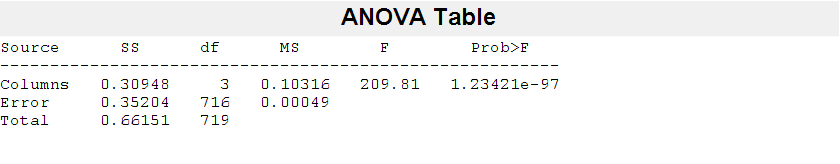

p = 1.2342e-97

tbl = 4×6 cell array
    {'Source' }    {'SS'    }    {'df' }    {'MS'        }    {'F'       }    {'Prob>F'    }
    {'Columns'}    {[0.3095]}    {[  3]}    {[    0.1032]}    {[209.8122]}    {[1.2342e-97]}
    {'Error'  }    {[0.3520]}    {[716]}    {[4.9167e-04]}    {0×0 double}    {0×0 double  }
    {'Total'  }    {[0.6615]}    {[719]}    {0×0 double  }    {0×0 double}    {0×0 double  }


stats = struct with fields:
    gnames: {4×1 cell}
         n: [180 180 180 180]
    source: 'anova1'
     means: [0.2139 0.2340 0.2266 0.2698]
        df: 716
         s: 0.0222


[p,tbl,stats] = anova1(Mean_values_conditions,groupnames)

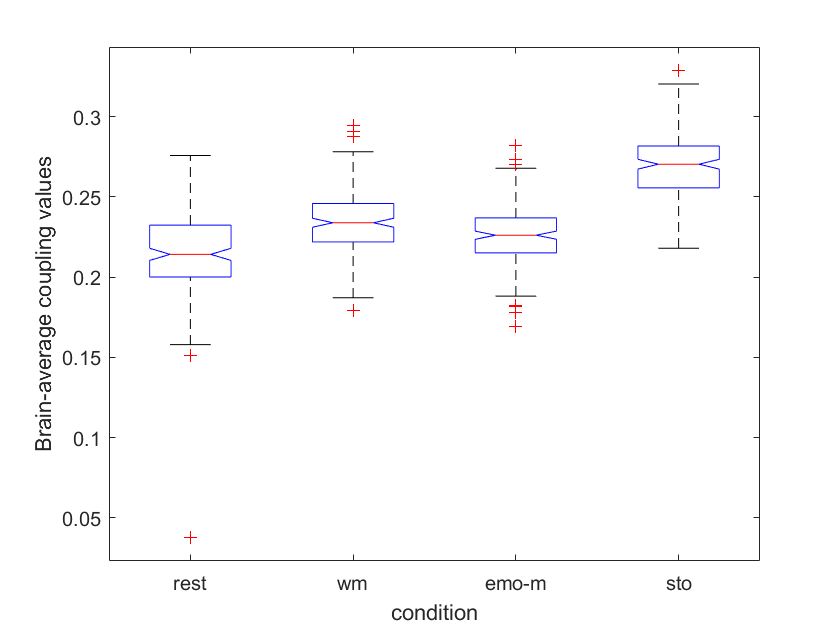

xlabel('condition')
ylabel('Brain-average coupling values')

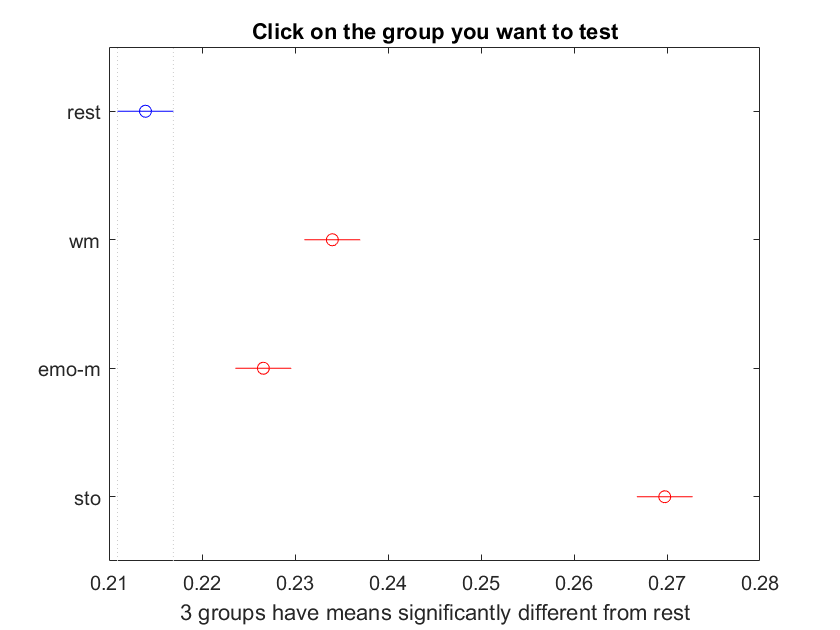

c =     1.0000    2.0000   -0.0261   -0.0201   -0.0141    0.0000
    1.0000    3.0000   -0.0187   -0.0127   -0.0067    0.0000
    1.0000    4.0000   -0.0618   -0.0558   -0.0498         0
    2.0000    3.0000    0.0014    0.0074    0.0134    0.0082
    2.0000    4.0000   -0.0417   -0.0357   -0.0297         0
    3.0000    4.0000   -0.0492   -0.0432   -0.0372         0


gnames = 4×1 cell array
    {'rest' }
    {'wm'   }
    {'emo-m'}
    {'sto'  }


[c,~,~,gnames] = multcompare(stats)

table = array2table(c,"VariableNames",["Group A", "Group B", "Lower Limit", "A-B", "Upper Limit", "P-value"])

table = 6×6 table
    Group A    Group B    Lower Limit       A-B       Upper Limit     P-value  
    _______    _______    ___________    _________    ___________    __________

       1          2        -0.026098     -0.020094     -0.014089     1.9605e-17
       1          3        -0.018681     -0.012676    -0.0066715     3.4928e-07
       1          4         -0.06184     -0.055835     -0.049831              0
       2          3        0.0014129     0.0074175      0.013422      0.0082025
       2          4        -0.041746     -0.035742     -0.029737              0
       3          4        -0.049164     -0.043159     -0.037155              0


**5. Run Repeated-measures ANOVA **

data = Mean_values_conditions

data =     0.2350    0.2447    0.2459    0.2806
    0.2156    0.2250    0.2324    0.2742
    0.2262    0.2279    0.2223    0.2752
    0.2061    0.2095    0.2049    0.2448
    0.2479    0.2300    0.2341    0.2377
    0.2108    0.2185    0.2175    0.2513
    0.2560    0.2542    0.2332    0.2553
    0.2758    0.2781    0.2577    0.3133
    0.2037    0.2466    0.2277    0.2632
    0.2027    0.2236    0.2050    0.2616


subjects = (1:size(data,1))';  % Subject IDs

% Convert to table format
T = array2table(data, 'VariableNames', {'rest','wm','emo-m','sto'});
T.Subjects = subjects;

% Define Table
numbers = [1; 2; 3; 4]

numbers =      1
     2
     3
     4


Infotable = array2table(numbers, 'VariableNames', {'Condition'})

Infotable = 4×1 table
    Condition
    _________

        1    
        2    
        3    
        4    



% Define the repeated-measures model
rm = fitrm(T, 'rest-sto ~ 1', 'WithinDesign', Infotable);

% Perform repeated-measures ANOVA
ranovatbl = ranova(rm)

ranovatbl = 2×8 table
                              SumSq     DF       MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                             _______    ___    __________    ______    __________    __________    __________    __________

    (Intercept):Condition    0.30948      3       0.10316    359.72    5.019e-128    2.2212e-98    1.1084e-99    1.0836e-44
    Error(Condition)           0.154    537    0.00028678                                                                  



% Display results
disp(ranovatbl)

                              SumSq     DF       MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                             _______    ___    __________    ______    __________    __________    __________    __________

    (Intercept):Condition    0.30948      3       0.10316    359.72    5.019e-128    2.2212e-98    1.1084e-99    1.0836e-44
    Error(Condition)           0.154    537    0.00028678                                                                  



% Perform post-hoc tests
multcompare(rm, 'Condition')

ans = 12×7 table
    Condition_1    Condition_2    Difference     StdErr        pValue        Lower        Upper   
    ___________    ___________    __________    _________    __________    _________    __________

         1              2          -0.020094    0.0019919    3.7683e-09    -0.025211     -0.014976
         1              3          -0.012676    0.0021861    4.3614e-08    -0.018292    -0.0070599
         1              4          -0.055835    0.0021178    3.7683e-09    -0.061276     -0.050395
         2              1           0.020094    0.0019919    3.7683e-09     0.014976      0.025211
         2              3          0.0074175    0.0013464     2.193e-07    0.0039584      0.010877
         2              4          -0.035742    0.0